clear; close all; clc;

[x, fs] = audioread('bjruf.wav');

N = 1024; % FFT size
L = N; % Window length = FFT size
R = L; % Hop size (no overlap for simplicity)

numBlocks = ceil(length(x)/R);
x = x(:)'; % make x a row vector

% Ensure sufficient padding
requiredLength = (numBlocks-1)*R + L;
x = [x zeros(1, requiredLength - length(x))];

% Initialize matrices
X_r_rect = zeros(numBlocks, N);
X_r_bartlett = zeros(numBlocks, N);
speech_presence_rect = zeros(numBlocks, 1);
speech_presence_bartlett = zeros(numBlocks, 1);

% Define windows
w_rect = rectwin(L)';
w_bartlett = bartlett(L)';

% Process blocks with rectangular window
for r = 1:numBlocks
    start_idx = (r-1)*R + 1;
    seg = x(start_idx:start_idx+L-1) .* w_rect;
    X_block = fft(seg, N);
    X_r_rect(r,:) = X_block;
end

% Process blocks with Bartlett window
for r = 1:numBlocks
    start_idx = (r-1)*R + 1;
    seg = x(start_idx:start_idx+L-1) .* w_bartlett;
    X_block = fft(seg, N);
    X_r_bartlett(r,:) = X_block;
end

% Speech detection for rectangular window
block_energies_rect = sum(abs(X_r_rect).^2, 2);
energy_threshold_rect = 0.1 * max(block_energies_rect);
speech_presence_rect(block_energies_rect > energy_threshold_rect) = 1;

% Speech detection for Bartlett window
block_energies_bartlett = sum(abs(X_r_bartlett).^2, 2);
energy_threshold_bartlett = 0.1 * max(block_energies_bartlett);
speech_presence_bartlett(block_energies_bartlett > energy_threshold_bartlett) = 1;

% Reconstruct signals
x_hat_rect = zeros(1, (numBlocks-1)*R + L);
x_hat_bartlett = zeros(1, (numBlocks-1)*R + L);

for r = 1:numBlocks
    % Rectangular window reconstruction
    x_r_block = ifft(X_r_rect(r,:), N);
    x_r_block = real(x_r_block(1:L));
    start_idx = (r-1)*R + 1;
    x_hat_rect(start_idx:start_idx+L-1) = x_hat_rect(start_idx:start_idx+L-1) + x_r_block;

    % Bartlett window reconstruction
    x_r_block = ifft(X_r_bartlett(r,:), N);
    x_r_block = real(x_r_block(1:L));
    x_hat_bartlett(start_idx:start_idx+L-1) = x_hat_bartlett(start_idx:start_idx+L-1) + x_r_block;
end

% Trim to original length
x_hat_rect = x_hat_rect(1:length(x));
x_hat_bartlett = x_hat_bartlett(1:length(x));

% Verify reconstruction quality
reconstruction_error_rect = norm(x_hat_rect - x) / norm(x);
reconstruction_error_bartlett = norm(x_hat_bartlett - x) / norm(x);

disp(['Reconstruction error (Rectangular): ' num2str(reconstruction_error_rect)]);

Reconstruction error (Rectangular): 2.8846e-16


disp(['Reconstruction error (Bartlett): ' num2str(reconstruction_error_bartlett)]);

Reconstruction error (Bartlett): 0.57728


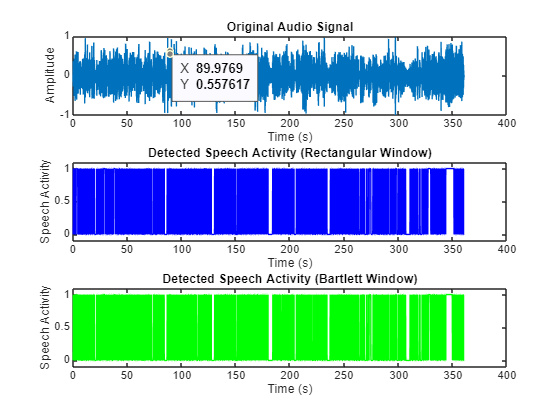


% Create 0-1 vectors for visualization
speech_binary_rect = zeros(size(x));
speech_binary_bartlett = zeros(size(x));

for r = 1:numBlocks
    start_idx = (r-1)*R + 1;
    end_idx = start_idx + L - 1;
    if end_idx > length(speech_binary_rect)
        end_idx = length(speech_binary_rect);
    end
    if speech_presence_rect(r) == 1
        speech_binary_rect(start_idx:end_idx) = 1;
    end
    if speech_presence_bartlett(r) == 1
        speech_binary_bartlett(start_idx:end_idx) = 1;
    end
end

t = (0:length(x)-1)/fs;

figure;
subplot(3,1,1);
plot(t, x);
xlabel('Time (s)');
ylabel('Amplitude');
title('Original Audio Signal');

subplot(3,1,2);
plot(t, speech_binary_rect, 'b');
xlabel('Time (s)');
ylabel('Speech Activity');
title('Detected Speech Activity (Rectangular Window)');
ylim([-0.1 1.1]);

subplot(3,1,3);
plot(t, speech_binary_bartlett, 'g');
xlabel('Time (s)');
ylabel('Speech Activity');
title('Detected Speech Activity (Bartlett Window)');
ylim([-0.1 1.1]);


% Play reconstructed sounds
% disp('Playing reconstructed sound with Rectangular Window...');
% soundsc(x_hat_rect, fs);
% pause(5);
% clear sound;
% 
% disp('Playing reconstructed sound with Bartlett Window...');
% soundsc(x_hat_bartlett, fs);
% pause(5);
% clear sound;
